# 波形数据去滑动平均值试验

## 1.加载实验波形数据

原始波形数据为：1999年11月29日`岫岩地震主震，辽宁地震台网大连台北南向记录`

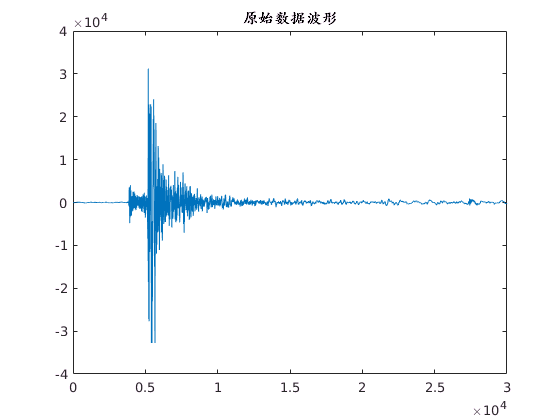

clear all;
oriData = load('M02_02_dalianN1.dat');
datLength= length(oriData);
figure();
plot(oriData);
title('原始数据波形');

## 2.原始数据中加入低频正弦噪声

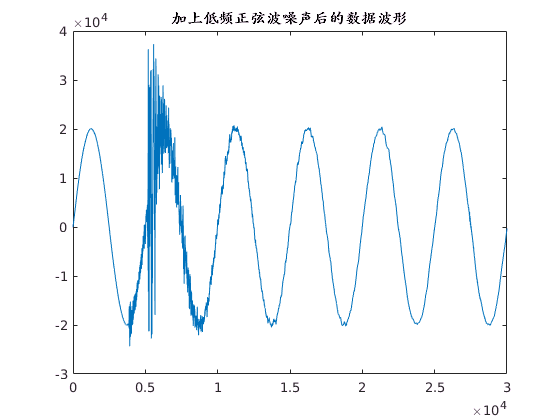

for i=1:datLength
    mixData(i) = oriData(i)+20000*sin(2*pi*i/5000); %低频正弦信号：20000*sin(2*pi*i/5000
end
figure(1);
plot(mixData);
title('加上低频正弦波噪声后的数据波形');

## 3.使用去滑动均值法，去除低频正弦波噪声

去除滑动段长为sliLength*2+1的滑动平均值

sliLength：滑动段长度

demData：去除低频正弦噪声后的波形数据

meaData：低频正弦噪声数据

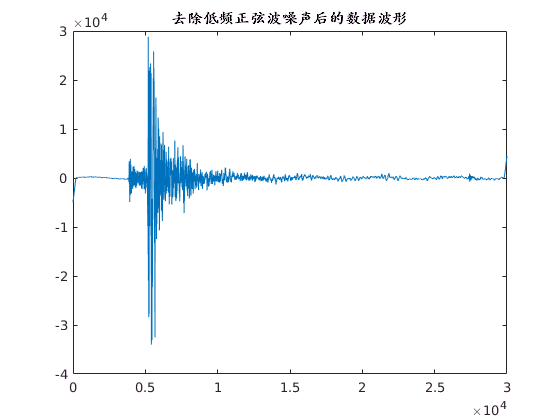

sliLength=200;
[demData,meaData]=M02_02_demmean_func(mixData,sliLength);
figure(2);
plot(demData);
title('去除低频正弦波噪声后的数据波形');

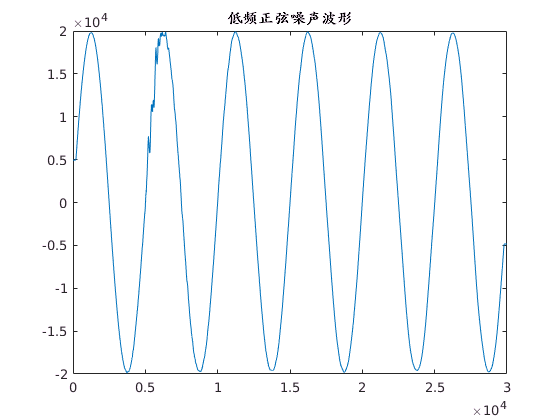

figure(3);
plot(meaData);
title('低频正弦噪声波形');

## 4.计算加入低频正弦波信号的波形数据振幅谱

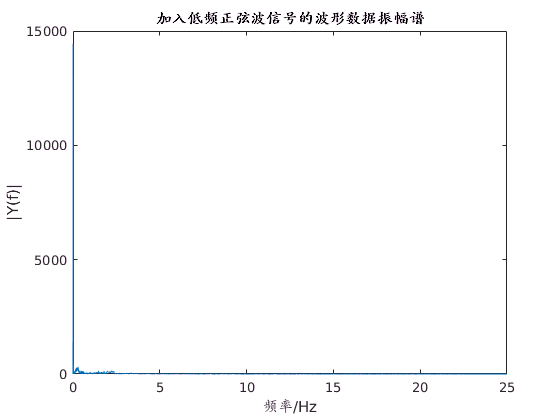

Fs=50; %采样率
NFFT = 2^nextpow2(datLength); 
Y= fft(mixData,NFFT)/datLength;
f = Fs/2*linspace(0,1,NFFT/2+1);
figure(4);
plot(f,2*abs(Y(1:NFFT/2+1))) ;
xlabel('频率/Hz');
ylabel('|Y(f)|');
title('加入低频正弦波信号的波形数据振幅谱');

## 5.计算去除低频正弦波信号后的波形数据振幅谱

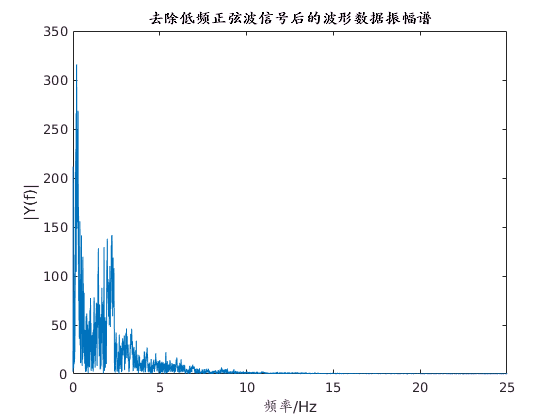

Fs=50; %采样率
NFFT = 2^nextpow2(datLength); 
Y = fft(demData,NFFT)/datLength;
f = Fs/2*linspace(0,1,NFFT/2+1);
figure(5);
plot(f,2*abs(Y(1:NFFT/2+1))) ;
xlabel('频率/Hz');
ylabel('|Y(f)|');
title('去除低频正弦波信号后的波形数据振幅谱');